# Unit Tests D Tree

## Intro

This shows off the full potential of `my_fitcensemble` with using the 4 different implemented methods. This file takes a long time to run which is expected as the classifiers are made in matlab and could be better optimised. The built in classifiers are all constructed using calls to C++ (I belive).

I will be using a 2d dataset to show them off as I can show the abstractions. This gets a little wierd for the Subspace and Random Forest methods, but I like the visualisations so I dont mind. The performance of these classifiers will be very bad but the abstractions are fun.

All methods are compatable with knn and trees, I did not make naive bayes so I do not know if there are any bugs with that classifier.

## Initialisation

The ensembles were implemented using the design philosophy of separation of concerns. This is shown as the `my_ClassificationEnsamble` class is only responsible for acting as a classifier, not for creating any classifiers. This job is handled by the `my_ClassifierFactory` and as the name suggests, it is a factory. The factory creates classifiers from `my_template` objects that have been supplied were the templates act as a grouping of the hyperparameter data for each `my_Classifier` class. 

rng(0);
[train_examples,test_examples,train_labels,test_labels] = prepare_dataset('sepal.csv',3,0.6);

Sample of data:

ans = 10×3 cell array
    {'sepal_length'}    {'sepal_width'}    {'species'}
    {[      5.1000]}    {[     3.5000]}    {'setosa' }
    {[      4.9000]}    {[          3]}    {'setosa' }
    {[      4.7000]}    {[     3.2000]}    {'setosa' }
    {[      4.6000]}    {[     3.1000]}    {'setosa' }
    {[           5]}    {[     3.6000]}    {'setosa' }
    {[      5.4000]}    {[     3.9000]}    {'setosa' }
    {[      4.6000]}    {[     3.4000]}    {'setosa' }
    {[           5]}    {[     3.4000]}    {'setosa' }
    {[      4.4000]}    {[     2.9000]}    {'setosa' }


test_examples size:	 60 2
test_labels size:	 60 1
train_examples size:	 90 2
train_labels size:	 90 1



% KNN template storing hyperparameter NumNeighbors
templates = {my_templateKNN('NumNeighbors',3) my_templateNB}

templates = 1×2 cell array
    {1×1 my_templateKNN}    {1×1 my_templateNB}



factory = my_ClassifierFactory(train_examples, train_labels, 'SoftVote', ...
    templates, 100, width(train_examples))

factory =   my_ClassifierFactory with properties:

                    X: [90×2 double]
                    Y: [90×1 categorical]
               Method: 'SoftVote'
             Learners: {[1×1 my_templateKNN]  [1×1 my_templateNB]}
        NPredToSample: 2
    NumLearningCycles: 100


From this we can create the Classifiers by calling the create method. All the Classifiers stored in the ms cell array are fully functional as shown.


ms = factory.makeClassifiers()

ms = 2×1 cell array
    {1×1 my_ClassificationKNN       }
    {1×1 my_ClassificationNaiveBayes}


% knn model
p_knn = ms{1}.predict(test_examples);
sum(p_knn == test_labels)/height(test_labels)

ans = 0.7833


% naive bayes model
p_nb = ms{2}.predict(test_examples);
sum(p_nb == test_labels)/height(test_labels)

ans = 0.7167

This is what happenes when fitc_ensamble is called, all of the classifiers are stored in the `Trained` property.


% by default the Method will be soft voting
m_en = my_fitcensemble(train_examples,train_labels,'Learners',templates)

m_en =   my_ClassificationEnsemble with properties:

            Trained: {2×1 cell}
         NumTrained: 2
                  X: [90×2 double]
                  Y: [90×1 categorical]
         ClassNames: [3×1 categorical]
    NumObservations: 90
    PredictorIndexs: [1 2]



m_en.Trained

ans = 2×1 cell array
    {1×1 my_ClassificationKNN       }
    {1×1 my_ClassificationNaiveBayes}



% knn model
p_knn = m_en.Trained{1}.predict(test_examples);
sum(p_knn == test_labels)/height(test_labels)

ans = 0.7833


% naive bayes model
p_nb = m_en.Trained{2}.predict(test_examples);
sum(p_nb == test_labels)/height(test_labels)

ans = 0.7167

## SoftVote

The following code should only be run on a dataset with 2 features as there is visualisation. Otherwise the code will not run.

The soft vote method is implemented just as sudjested in Lab 8, as all of these methods are. Here we will train it on the `sepal.csv` once again.

rng(0);
[train_examples,test_examples,train_labels,test_labels] = prepare_dataset('sepal.csv',3,0.6);

Sample of data:

ans = 10×3 cell array
    {'sepal_length'}    {'sepal_width'}    {'species'}
    {[      5.1000]}    {[     3.5000]}    {'setosa' }
    {[      4.9000]}    {[          3]}    {'setosa' }
    {[      4.7000]}    {[     3.2000]}    {'setosa' }
    {[      4.6000]}    {[     3.1000]}    {'setosa' }
    {[           5]}    {[     3.6000]}    {'setosa' }
    {[      5.4000]}    {[     3.9000]}    {'setosa' }
    {[      4.6000]}    {[     3.4000]}    {'setosa' }
    {[           5]}    {[     3.4000]}    {'setosa' }
    {[      4.4000]}    {[     2.9000]}    {'setosa' }


test_examples size:	 60 2
test_labels size:	 60 1
train_examples size:	 90 2
train_labels size:	 90 1



templates = {my_templateKNN('NumNeighbors',3) my_templateNB}

templates = 1×2 cell array
    {1×1 my_templateKNN}    {1×1 my_templateNB}


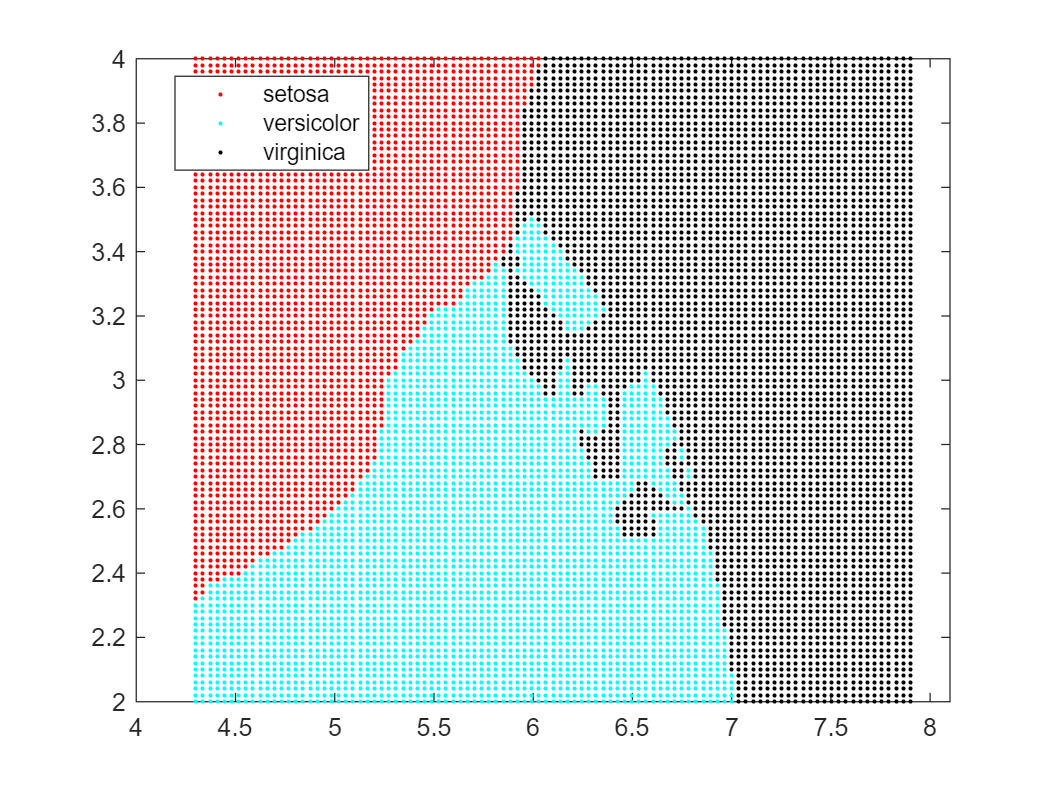

m_en = my_fitcensemble(train_examples,train_labels,'Learners',templates);

visualise_abstraction(m_en,'rck');

p_en = m_en.predict(test_examples);

% it gives a better result than the worst classifier in it.
sum(p_en == test_labels)/height(test_labels)

ans = 0.7833

The code is modular and can easily be used to add different classifiers with different hyperparametrs. Here we add a `my_ClassificationTree` to the ensamble.


templates = {my_templateKNN('NumNeighbors',3) my_templateNB my_templateTree('MinParentSize',5)}

templates = 1×3 cell array
    {1×1 my_templateKNN}    {1×1 my_templateNB}    {1×1 my_templateTree}


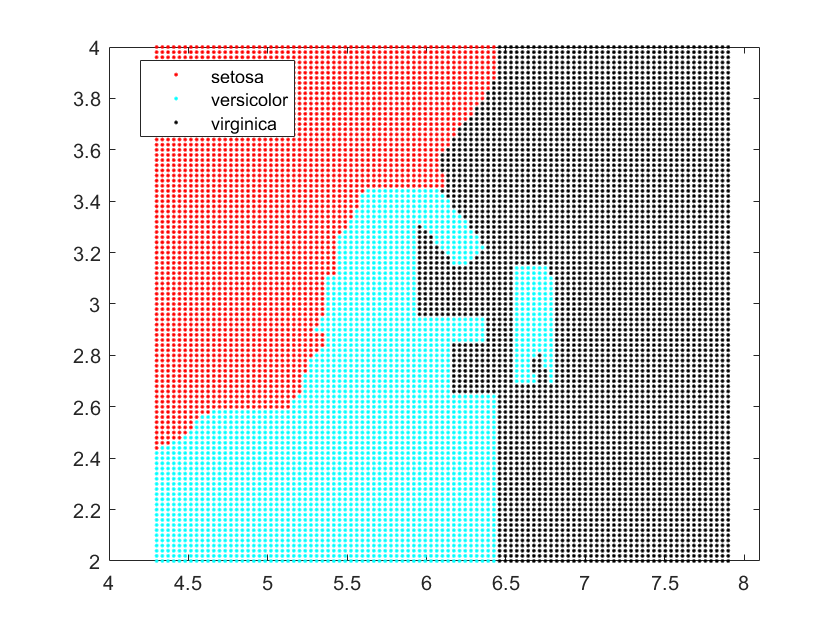

m_en = my_fitcensemble(train_examples,train_labels,'Learners',templates);

visualise_abstraction(m_en,'rck');

p_en = m_en.predict(test_examples);

% it gives a better result than the worst classifier in it.
sum(p_en == test_labels)/height(test_labels)

ans = 0.7833

## Bagging

I will first state that the models made on this course are far slower than the built in models beacause they run in c++ code not matlab code and they are better optimised. This will lead to the following opperations being very slow.

By default bagging creates 100 classifiers for each specified template. They are given observations that can be repeated. There is no option to disable this (didnt want too many hyperparameters).

rng(0);
[train_examples,test_examples,train_labels,test_labels] = prepare_dataset('sepal.csv',3,0.6);

m_en = my_fitcensemble(train_examples, train_labels, ...
    'Method', 'Bag', 'Learners', my_templateKNN('NumNeighbors',3));

% 100 trained knn classifiers
m_en.Trained

ans = 100×1 cell array
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}



% train data at 50th knn classifier
m_en.Trained{50}.X

ans =     5.0000    3.4000
    4.6000    3.1000
    4.4000    2.9000
    7.9000    3.8000
    4.8000    3.4000
    4.4000    3.2000
    5.0000    3.5000
    5.1000    3.8000
    4.9000    3.1000
    5.5000    3.5000


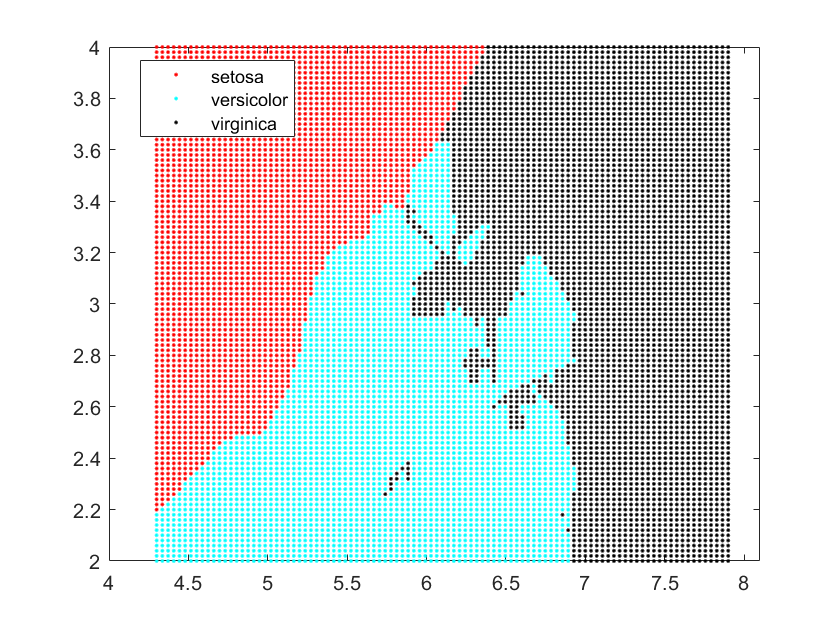


% if lets say our knn used a kd tree <:) it would run alot faster!
% takes about 2 mins on school machine :/
visualise_abstraction(m_en,'rck');

p_en = m_en.predict(test_examples);

sum(p_en == test_labels)/height(test_labels)

ans = 0.8000

## Subspace

This one will be wierd, since the data only has 2 axis. We will specify that each classifier will only have 1 axis. This method is favourable in high feature datasets. We will only train 50 classifiers by using the `NumLearningCycles` hyperparameter and we will use specifically 1 axis by using the `NPredToSample` hyperparameter.

This is done by storing the axis of the features used in `PredictorIndexs`.

rng(0);
[train_examples,test_examples,train_labels,test_labels] = prepare_dataset('sepal.csv',3,0.6);

m_en = my_fitcensemble(train_examples, train_labels, ...
    'Method', 'Subspace', 'Learners', my_templateKNN('NumNeighbors',3), ...
    'NumLearningCycles',50, 'NPredToSample',1);

% 50 trained knn classifiers
m_en.Trained

ans = 50×1 cell array
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}
    {1×1 my_ClassificationKNN}



% train data at 50th knn classifier
m_en.Trained{50}.X

ans =     5.7000
    5.5000
    6.8000
    7.7000
    7.2000
    5.2000
    7.7000
    5.6000
    6.0000
    4.7000



% index of featur used in prediction
m_en.Trained{50}.PredictorIndexs

ans = 1

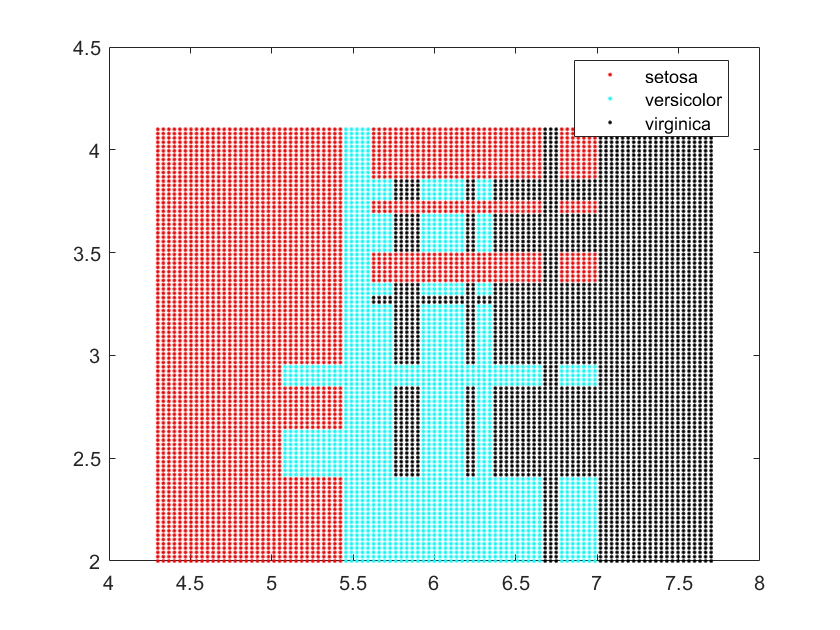


% takes about 1 mins on school machine :/
visualise_abstraction(m_en,'rck');

p_en = m_en.predict(test_examples);

sum(p_en == test_labels)/height(test_labels)

ans = 0.6833

The abstraction looks the way it does as each classifier looks to only have linier functionality! Very interesting. Looks more like a decision tree abstraction.

## Subspace ionosphere.csv

This compares the matlab model to mine. Trees can be used here aswell, I do not know if NB can be used.

rng(0);
[train_examples,test_examples,train_labels,test_labels] = prepare_dataset('ionosphere.csv',35,0.6);

Sample of data:

ans = 10×35 cell array
    {'a01'}    {'a02'}    {'a03'   }    {'a04'    }    {'a05'    }    {'a06'    }    {'a07'    }    {'a08'    }    {'a09'   }    {'a10'    }    {'a11'   }    {'a12'    }    {'a13'   }    {'a14'    }    {'a15'    }    {'a16'    }    {'a17'    }    {'a18'    }    {'a19'    }    {'a20'    }    {'a21'    }    {'a22'    }    {'a23'    }    {'a24'    }    {'a25'    }    {'a26'    }    {'a27'    }    {'a28'    }    {'a29'    }    {'a30'    }    {'a31'    }    {'a32'    }    {'a33'        }    {'a34'    }    {'class'}
    {[  1]}    {[  0]}    {[0.9954]}    {[-0.0589]}    {[ 0.8524]}    {[ 0.0231]}    {[ 0.8340]}    {[-0.3771]}    {[     1]}    {[ 0.0376]}    {[0.8524]}    {[-0.1776]}    {[0.5976]}    {[-0.4495]}    {[ 0.6054]}    {[-0.3822]}    {[ 0.8436]}    {[-0.3854]}    {[ 0.5821]}    {[-0.3219]}    {[ 0.5697]}    {[-0.2967]}    {[ 0.3695]}    {[-0.4736]}    {[ 0.5681]}    {[-0.5117]}    {[ 0.4108]}    {[-0.4617]}    {[ 0.2127]}    {[-0.3409]}    {[ 0.4227]}    {[-0

test_examples size:	 140 34
test_labels size:	 140 1
train_examples size:	 211 34
train_labels size:	 211 1



my_en = my_fitcensemble(train_examples, train_labels, 'Method', 'Subspace', ...
    'Learners', my_templateKNN(), 'NPredToSample', 5);

mat_en = fitcensemble(train_examples, train_labels, 'Method', 'Subspace', ...
    'Learners', templateKNN(), 'NPredToSample', 5);

% index of featur used in prediction
my_en.Trained{50}.PredictorIndexs

ans =      1     4    10    20    29


mat_en.Trained{50}.PredictorNames

ans = 1×5 cell array
    {'x3'}    {'x10'}    {'x14'}    {'x20'}    {'x34'}



% takes about 1 mins on school machine :/
% my prediction
p_my = my_en.predict(test_examples);
sum(p_my == test_labels)/height(test_labels)

ans = 0.9357


% matlab
p_mat = mat_en.predict(test_examples);
sum(p_mat == test_labels)/height(test_labels)

ans = 0.9286

As seen the performance is simmilar.

## Random Forest

I have missinterpreted what it is to have a random forets, I thoght it ment each tree is is only trained on a specific amount of features rather than at each split n features are chosen to evaluate. To implement this would be tedious and I would have to change my Tree file which I am not willing to do as I do not want to risk braking my code.